# Actividad 1 (Mapeo de coordenadas)

Elaborado por: Marcos Allen Martínez Cortés  |  A01737939

**Implementar **el código requerido para generar un **mapeo** del siguiente sistema global al sistema local de referencia del robot móvil y viceversa.

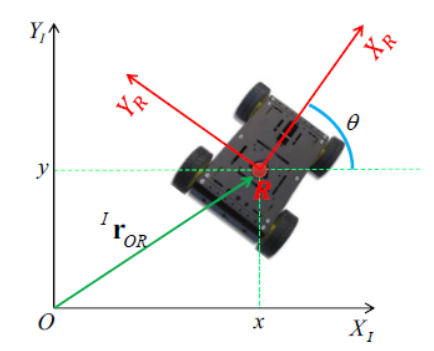

**Obtener **el mapeo de las siguientes coordenadas inerciales, hacia un marco de referencia local y comprobar si se obtienen las coordenadas iniciales con el mapeo inverso.

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms x(t) y(t) th(t)  t  %Grados de Libertad del robot móvil

%Creamos el vector de posición 
xi_inercial= [x; y; th];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (xi_inercial);

/  x(t) \
|       |
|  y(t) |
|       |
\ th(t) /




%Creamos el vector de velocidades
xip_inercial= diff(xi_inercial, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (xip_inercial);

/   d      \
|  -- x(t) |
|  dt      |
|          |
|   d      |
|  -- y(t) |
|  dt      |
|          |
|  d       |
| -- th(t) |
\ dt       /



En robótica móvil 2D se suele escribir posición y orientación en un solo vector.

%Defino mi vector de posición y matriz de rotación
P(:,:,1)= [x;y;th]; %Viene siendo "xi_inercial"
%Matriz de rotación alrededor del eje z.... 
R(:,:,1)= [cos(th) -sin(th)  0;
       sin(th)  cos(th)  0;
       0        0        1];


%Realizo mi transformación del marco de referencia global al local.... 
xi_local=R(:,:,1)*P(:,:,1)

$$xi\_local = \left(\begin{array}{c} \cos\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)-\sin\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)\\ \cos\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)+\sin\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)\\ \mathrm{th}\left(t\right) \end{array}\right)$$

a) **(-5, 9, -2°)**

Para el ejemplo, primero se define la posición del robot en el sistema inercial.

%Defino coordenadas inerciales para un tiempo 1
x1 = -5;    % Posicion inicial eje x
y1 = 9;   % Posicion inicial eje y

Y, se define su orientación, convertida de grados a radianes (con lo que trabaja MATLAB).

th1= deg2rad(-2);   % Orientacion inicial del robot

Se define el vector de posición, donde z es 0 porque se está trabajando en 2D en el plano XY.

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];

Como estamos trabajando en 2D, la rotación es sobre el eje Z.

Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

Se convierte la posición desde el sistema inercial al sistema local del robot. Es como ver el punto desde la perspectiva del robot.

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -4.6829
    9.1690
         0


Se calcula la magnitud, que sería la distancia al origen.

%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 10.2956

Se calcula la inversa de la rotación, ya que aplicando la transformación inversa (del sistema local al sistema inercial) se debe recuperar el vector de posición original.

%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =    -5.0000
    9.0000
         0


toc

Elapsed time is 5.058210 seconds.


Para los siguientes ejemplos se lleva a cabo el mismo procedimiento.

b) **(-3, 8, 63°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = -3;    % Posicion inicial eje x
y1 = 8;   % Posicion inicial eje y
th1= deg2rad(63);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -8.4900
    0.9589
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 8.5440


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =     -3
     8
     0



toc

Elapsed time is 0.136608 seconds.


c) **(5, -2, 90°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 5;    % Posicion inicial eje x
y1 = -2;   % Posicion inicial eje y
th1= deg2rad(90);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =     2.0000
    5.0000
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 5.3852


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =      5
    -2
     0



toc

Elapsed time is 0.127390 seconds.


d) **(0, 0, 180°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 0;    % Posicion inicial eje x
y1 = 0;   % Posicion inicial eje y
th1= deg2rad(180);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =      0
     0
     0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 0


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =      0
     0
     0



toc

Elapsed time is 0.033451 seconds.


e) **(-6, 3, -55°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = -6;    % Posicion inicial eje x
y1 = 3;   % Posicion inicial eje y
th1= deg2rad(-55);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -0.9840
    6.6356
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 6.7082


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =    -6.0000
    3.0000
         0



toc

Elapsed time is 0.038613 seconds.


f) **(10, -2, 45°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 10;    % Posicion inicial eje x
y1 = -2;   % Posicion inicial eje y
th1= deg2rad(45);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =     8.4853
    5.6569
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 10.1980


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =     10
    -2
     0



toc

Elapsed time is 0.028549 seconds.


g) **(9, 1, 88°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 9;    % Posicion inicial eje x
y1 = 1;   % Posicion inicial eje y
th1= deg2rad(88);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -0.6853
    9.0294
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 9.0554


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =      9
     1
     0



toc

Elapsed time is 0.033561 seconds.


h) **(5, 2, 33°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 5;    % Posicion inicial eje x
y1 = 2;   % Posicion inicial eje y
th1= deg2rad(33);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =     3.1041
    4.4005
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 5.3852


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =      5
     2
     0



toc

Elapsed time is 0.027738 seconds.


i) **(-1, -1, 21°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = -1;    % Posicion inicial eje x
y1 = -1;   % Posicion inicial eje y
th1= deg2rad(21);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -0.5752
   -1.2919
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 1.4142


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =    -1.0000
   -1.0000
         0



toc

Elapsed time is 0.030213 seconds.


j) **(6, 4, -40°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 6;    % Posicion inicial eje x
y1 = 4;   % Posicion inicial eje y
th1= deg2rad(-40);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =     7.1674
   -0.7925
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 7.2111


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =     6.0000
    4.0000
         0



toc

Elapsed time is 0.033615 seconds.


k) **(5, 7, 72°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 5;    % Posicion inicial eje x
y1 = 7;   % Posicion inicial eje y
th1= deg2rad(72);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -5.1123
    6.9184
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 8.6023


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =      5
     7
     0



toc

Elapsed time is 0.027450 seconds.


l) **(7, 7,  30°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 7;    % Posicion inicial eje x
y1 = 7;   % Posicion inicial eje y
th1= deg2rad(30);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =     2.5622
    9.5622
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 9.8995


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =     7.0000
    7.0000
         0



toc

Elapsed time is 0.032782 seconds.


m) **(11, -4, 360°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 11;    % Posicion inicial eje x
y1 = -4;   % Posicion inicial eje y
th1= deg2rad(360);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    11.0000
   -4.0000
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 11.7047


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =     11
    -4
     0



toc

Elapsed time is 0.028026 seconds.


n) **(20, 5, 270°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 20;    % Posicion inicial eje x
y1 = 5;   % Posicion inicial eje y
th1= deg2rad(270);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =     5.0000
  -20.0000
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 20.6155


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =     20
     5
     0



toc

Elapsed time is 0.026525 seconds.


ñ) **(10, 9, 345°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 10;    % Posicion inicial eje x
y1 = 9;   % Posicion inicial eje y
th1= deg2rad(345);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    11.9886
    6.1051
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 13.4536


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =    10.0000
    9.0000
         0



toc

Elapsed time is 0.026848 seconds.


o) **(-9, -8, 8°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = -9;    % Posicion inicial eje x
y1 = -8;   % Posicion inicial eje y
th1= deg2rad(8);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -7.7990
   -9.1747
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 12.0416


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =    -9.0000
   -8.0000
         0



toc

Elapsed time is 0.026466 seconds.


p) **(1, 1, 60°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 1;    % Posicion inicial eje x
y1 = 1;   % Posicion inicial eje y
th1= deg2rad(60);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -0.3660
    1.3660
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 1.4142


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =     1.0000
    1.0000
         0



toc

Elapsed time is 0.027446 seconds.


q) **(3, 1, -30°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 3;    % Posicion inicial eje x
y1 = 1;   % Posicion inicial eje y
th1= deg2rad(-30);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =     3.0981
   -0.6340
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 3.1623


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =     3.0000
    1.0000
         0



toc

Elapsed time is 0.027831 seconds.


r) **(15, 2, 199°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = 15;    % Posicion inicial eje x
y1 = 2;   % Posicion inicial eje y
th1= deg2rad(199);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =   -13.5316
   -6.7746
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 15.1327


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =    15.0000
    2.0000
         0



toc

Elapsed time is 0.039404 seconds.


s) **(-10, 0, 300°)**

tic
%Defino coordenadas inerciales para un tiempo 1
x1 = -10;    % Posicion inicial eje x
y1 = 0;   % Posicion inicial eje y
th1= deg2rad(300);   % Orientacion inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; 0];
Rot_1= [cos(th1) -sin(th1) 0;
    sin(th1)  cos(th1) 0;
    0         0        1];

%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    -5.0000
    8.6603
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 10


%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =   -10.0000
    0.0000
         0



toc

Elapsed time is 0.026005 seconds.
